addpath('Classes')
addpath('Simulink Models')
addpath('Functions')

%Make sure symprefs are set correctly for this script
sympref('MatrixWithSquareBrackets',true);
sympref('AbbreviateOutput', false);
sympref('FloatingPoint',true);
sympref('TypesetOutput',true);


# Angular Input Sliding Mode Control, Try 1 Script

%Create a variable definitions object if one does not already exist. 
if (~exist('VDefs', 'var')) 

    VDefs = Var_Defs;  %Create an object of the class Var_Defs

end 

%Create a u-joint Kinematics object if one does not already exist. 
if (~exist('UJ_Knmtcs', 'var')) 

    UJ_Knmtcs = UJ_Knmtcs(VDefs); %Create an object of the class UJ_Knmtcs
    UJ_Knmtcs.derive_all; %Run all of its derivation functions

end 

%Create a ball-plate kinematics object if one does not already exist. 
if (~exist('BP_Knmtcs', 'var')) 

    BP_Knmtcs = BP_Knmtcs(VDefs, UJ_Knmtcs); %Create an object of the class BP_Knmtcs
    BP_Knmtcs.Derive_Both; %Derive all the kinematic equations for the ball-plate system
end 

%Create a ball-plate kinetics object if one does not already exist. 
if (~exist('BP_Kinetics', 'var')) 

    BP_Kinetics = BP_Kinetics(VDefs, UJ_Knmtcs, BP_Knmtcs); %Create an object of the class BP_Kinetics
    BP_Kinetics.Derive_NL_EOMs; %Derive the nonlinear equations of motion for the ball-plate system
    BP_Kinetics.Num_Params_n_Assumptions; %Input numerical parameters and assumptions

end 


%Create a linearized EOMs object if one does not already exist. 
if (~exist('Lnrzed_EOMs', 'var')) 

    Lnrzed_EOMs = Lnrzed_EOMs(VDefs, BP_Kinetics); %Create an object of the class Lnrzed_EOMs
    Lnrzed_EOMs.Derive_8th_Ordr_Lin_Sys;
    Lnrzed_EOMs.Derive_4th_Ordr_Lin_Sys
end 

$$ans = \left[\begin{array}{cccc} 0 & 1 & 0 & 0\\ -1.8786 & 0 & 4.1026 & 0\\ 0 & 0 & 0 & 1\\ 20.2622 & 0 & 31.3281 & 0 \end{array}\right]$$


%Create a nonlinear decoupled EOMs object if one does not already exist. 
if (~exist('NL_Dcpld_EOMs', 'var')) 

    NL_Dcpld_EOMs = NL_Dcpld_EOMs(VDefs, BP_Kinetics); %Create an object of the class NL_Dcpld_EOMs
    NL_Dcpld_EOMs.Num_Params;

end

%Define a few symbolic variables to be used
syms lambda_x lambda_y S_x S_y S_dot_x S_dot_y u_x u_y u_hat_x u_hat_y K_s


## System 1 - x direction

### Sliding Surface for global x location of the ball 


$$\begin{array}{l}

S_x = e_{\dot{x}} + \lambda_x \, e_x\\

\end{array}

$$


e_x = VDefs.x_s - VDefs.x;
e_x_dot = VDefs.x_dot_s - VDefs.x_dot;
Sx_eqn = S_x ==  e_x_dot + lambda_x*(e_x)

$$Sx\_eqn = S_{x}={\dot{x}}_{s}-\dot{x}-\lambda_{x}\,\left(x-x_{s}\right)$$

xdd = rhs(isolate(NL_Dcpld_EOMs.Num_SumMBall_x, VDefs.x_ddot));

In the sum of moments for the ball, call $sin(\beta)~u_1$. 

xdd = subs(xdd, sin(VDefs.beta), u_x)

$$xdd = 0.7143\,{\dot{\beta }}^{2}\,x+7.0071\,u_{x}-0.0927\,\ddot{\beta }$$

Sdx_eqn = S_dot_x == VDefs.x_ddot_s - xdd + lambda_x*(e_x_dot)

$$Sdx\_eqn = {\dot{S}}_{x}=0.0927\,\ddot{\beta }-7.0071\,u_{x}+{\ddot{x}}_{s}-\lambda_{x}\,\left(\dot{x}-{\dot{x}}_{s}\right)-0.7143\,{\dot{\beta }}^{2}\,x$$

### Nullifying $\mathbf{sin(\beta)}$ Input 

Finding the input, $u_1(\beta) = sin(\beta)$, required to zero out the derivative of the sliding surface. Allows us to determine wether or not the sliding surface is attractive given the angular constraints (if nullifying input exceeds the constraints, it may not be possible to make the surface attractive). 

u_hat_x_eqn = u_hat_x == rhs(isolate(subs(Sdx_eqn, S_dot_x, 0),u_x))

$$u\_hat\_x\_eqn = {\hat{u}}_{x}=0.0132\,\ddot{\beta }+0.1427\,{\ddot{x}}_{s}-0.1427\,\lambda_{x}\,\left(\dot{x}-{\dot{x}}_{s}\right)-0.1019\,{\dot{\beta }}^{2}\,x$$


%Test Nullifying Input
simplify(subs(rhs(Sdx_eqn ), u_x, rhs(u_hat_x_eqn)))

$$ans = 0$$

### Lyapunov Function and Switching Law


$$\begin{array}{l}

V_x = \frac{S_x^^2}{2}\\

\dot{V}_x = S_x \, \dot{S}_x

\end{array}$$


Vd1 = S_x*rhs(Sdx_eqn)

$$Vd1 = -S_{x}\,\left(7.0071\,u_{x}-0.0927\,\ddot{\beta }-{\ddot{x}}_{s}+\lambda_{x}\,\left(\dot{x}-{\dot{x}}_{s}\right)+0.7143\,{\dot{\beta }}^{2}\,x\right)$$


b_Sxd = double(equationsToMatrix(rhs(Sdx_eqn), u_x)) %Input matrix for u_x in S1dot equation

b_Sxd = -7.0071


switching_law1 = -K_s/b_Sxd*sign(S_x) %

$$switching\_law1 = 0.1427\,K_{s}\,\mathrm{sign}\left(S_{x}\right)$$

## System 2 - y direction

### Sliding Surface for global x location of the ball 


$$\begin{array}{l}

S_y = e_{\dot{y}} + \lambda_y \, e_y\\

\end{array}

$$


e_y = VDefs.y_s - VDefs.y;
e_y_dot = VDefs.y_dot_s - VDefs.y_dot;
Sy_eqn = S_y ==  e_y_dot + lambda_y*(e_y)

$$Sy\_eqn = S_{y}={\dot{y}}_{s}-\dot{y}-\lambda_{y}\,\left(y-y_{s}\right)$$

ydd = rhs(isolate(NL_Dcpld_EOMs.Num_SumMBall_y, VDefs.y_ddot));

In the sum of moments for the ball, call $sin(\gamma)~u_2$. 

ydd = subs(ydd, sin(VDefs.gamma), u_y)

$$ydd = 0.7143\,{\dot{\gamma }}^{2}\,y-7.0071\,u_{y}+0.0927\,\ddot{\gamma }$$

Sdy_eqn = S_dot_y == VDefs.y_ddot_s - ydd + lambda_y*(e_y_dot)

$$Sdy\_eqn = {\dot{S}}_{y}=7.0071\,u_{y}-0.0927\,\ddot{\gamma }+{\ddot{y}}_{s}-\lambda_{y}\,\left(\dot{y}-{\dot{y}}_{s}\right)-0.7143\,{\dot{\gamma }}^{2}\,y$$

### Nullifying $\mathbf{sin(\gamma)}$ Input 

Finding the input, $u_2(\gamma) = sin(\gamma)$, required to zero out the derivative of the sliding surface. Allows us to determine wether or not the sliding surface is attractive given the angular constraints (if nullifying input exceeds the constraints, it may not be possible to make the surface attractive). 

u_hat_y_eqn = u_hat_y == rhs(isolate(subs(Sdy_eqn, S_dot_y, 0),u_y))

$$u\_hat\_y\_eqn = {\hat{u}}_{y}=0.0132\,\ddot{\gamma }-0.1427\,{\ddot{y}}_{s}+0.1427\,\lambda_{y}\,\left(\dot{y}-{\dot{y}}_{s}\right)+0.1019\,{\dot{\gamma }}^{2}\,y$$


%Test Nullifying Input
simplify(subs(rhs(Sdy_eqn ), u_y, rhs(u_hat_y_eqn)))

$$ans = 0$$

### Lyapunov Function and Switching Law


$$\begin{array}{l}

V_y = \frac{S_y^^2}{2}\\

\dot{V}_y = S_y \, \dot{S}_y

\end{array}$$


Vd2 = S_y*rhs(Sdy_eqn)

$$Vd2 = -S_{y}\,\left(0.0927\,\ddot{\gamma }-7.0071\,u_{y}-{\ddot{y}}_{s}+\lambda_{y}\,\left(\dot{y}-{\dot{y}}_{s}\right)+0.7143\,{\dot{\gamma }}^{2}\,y\right)$$


b_Syd = double(equationsToMatrix(rhs(Sdy_eqn), u_y)) %Input matrix for u_y in S2dot equation

b_Syd = 7.0071


switching_law2 = -K_s/b_Syd*sign(S_y)

$$switching\_law2 = -0.1427\,K_{s}\,\mathrm{sign}\left(S_{y}\right)$$

## Desired Trajectory in x and y

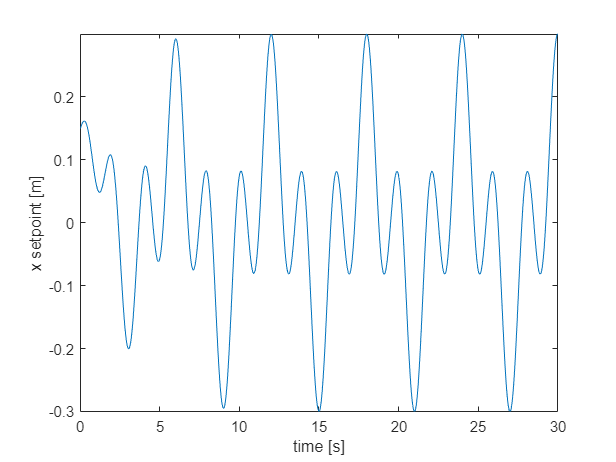

%Ideal trajectory parameters
r_sim = .3; % radius of trajectory [m] Touch screen is about 30 cm wide
% freq = 1/9; %rotations per second: 1/9 for octofolium is about as fast as it gets
% freq = 1/6; %rotations per second:  1/6 for quadrifolium is about as fast as it gets
freq = 1/6;
omega_sim =  2*pi*freq; %angular frequency of circular trajectory 


%Specify initial conditions and compute initial outputs
x_0 = 1/2*[r_sim; 0; 0; 0; r_sim; 0; 0; 0]; %As if the ball was at rest in the center of the plate - the control objective of any regulator designed for the system


%Ideal trajectory symfuns
%Figure 8
% des_traj_sym_x(VDefs.t) = r_sim*sin(omega_sim*VDefs.t)*cos(omega_sim*VDefs.t);
% des_traj_sym_y(VDefs.t) = r_sim*sin(omega_sim*VDefs.t);

%Circle
% des_traj_sym_x(VDefs.t) = r_sim*sin(omega_sim*VDefs.t);
% des_traj_sym_y(VDefs.t) = r_sim*cos(omega_sim*VDefs.t);

%Simple STAY AT THE ICs SETPOINT for tuning inner angular loops
% des_traj_sym_x(VDefs.t) = x_0(1) + 0*VDefs.t;
% des_traj_sym_y(VDefs.t) = x_0(5) + 0*VDefs.t;

%Rose curve specified by k
n = 2;
d = 1;
k = n/d;
des_traj_sym_x(VDefs.t) = r_sim*cos(k*omega_sim*VDefs.t)*cos(omega_sim*VDefs.t);
des_traj_sym_y(VDefs.t) = r_sim*cos(k*omega_sim*VDefs.t)*sin(omega_sim*VDefs.t);


%Overlay first order smoothing functions
Tau = 2; %Time constant for first overlayed order response - latest working 2


%Trajectory symfuns with first order smoothing overlayed and a smooth transition from the
%initial conditions
des_traj_sym_x(VDefs.t) = des_traj_sym_x(VDefs.t)*(1-exp(-VDefs.t/Tau)) + x_0(1)*exp(-VDefs.t/Tau);
des_traj_sym_y(VDefs.t) = des_traj_sym_y(VDefs.t)*(1-exp(-VDefs.t/Tau)) + x_0(5)*exp(-VDefs.t/Tau);

figure
fplot(des_traj_sym_x) 
xlim([0 2*pi/omega_sim*5]); 
ylabel('x setpoint [m]')
xlabel('time [s]')

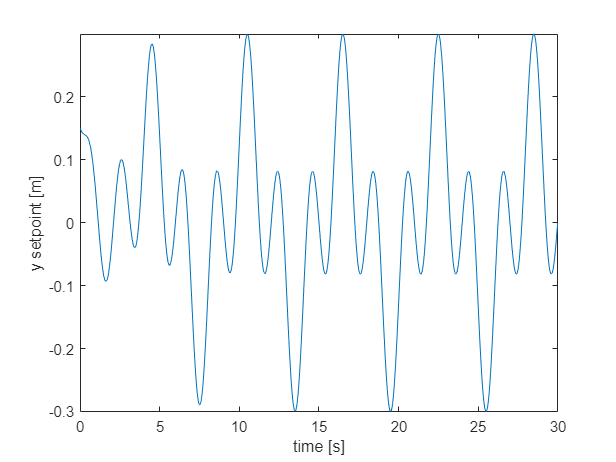


figure
fplot(des_traj_sym_y) 
xlim([0 2*pi/omega_sim*5]); 
ylabel('y setpoint [m]')
xlabel('time [s]')


%Trajectory's derivatives
des_traj_sym_dot_x(VDefs.t) = diff(des_traj_sym_x(VDefs.t),VDefs.t);
des_traj_sym_dot_y(VDefs.t) = diff(des_traj_sym_y(VDefs.t),VDefs.t);
des_traj_sym_ddot_x(VDefs.t) = diff(des_traj_sym_x(VDefs.t),VDefs.t,2);
des_traj_sym_ddot_y(VDefs.t) = diff(des_traj_sym_y(VDefs.t),VDefs.t,2);

%x_s_vec and y_s_vec
des_traj_sym_x = [des_traj_sym_x;des_traj_sym_dot_x;des_traj_sym_ddot_x];
des_traj_sym_y = [des_traj_sym_y;des_traj_sym_dot_y;des_traj_sym_ddot_y];

## Numerical Control Parameters


%Choose numerical lambdas 
lambda_x_num = 1/1; %1/1  latest that works pretty damn well for moderately fast trajectories and well enough for speed that pushes the limit
lambda_y_num = lambda_x_num;

%Max torque
Tmax = VDefs.Tmax; % [Nm] Comes from rated torque of Scott's motors and the gear ratio assumption

%Max angle
Angle_max = deg2rad(20) %Used to saturate the requested angular setpoint for the inner loop 20 has been working pretty well

Angle_max = 0.3491


%Switching gain
K_switch = sin(Angle_max)/2; %latest working is sin(Angle_max)/2 with S_BL_value = 0.5 

%Low pass filter time constant for angular setpoints
tau_angle = 0.09; %0.09 latest working with decent amplitude and imperceptible phase lag (if the nullifying input is used). 0.05 works for no nullifying input

%Boundary layer size
S_BL_value = 0.5; %.5 latest working with the K_switch of sin(Angle_max)/2

%Boundary Layer Gain
%BL_gain = (K_switch)/S_BL_value; %To prevent fast switches at the border of the boundary layer, need to have the cuttoff angle be equal to the switching angle
%Gain in the BL is then coupled to the size of the boundary layer. 
BL_gain = (K_switch)/S_BL_value; %0.1 worked well with 1/6 Hz

## Inner Loop Controller Design

syms T_tilde_beta T_tilde_gamma s

%Compute the ball-disturbance rejecting feed-forward torque
betadd_lin_eqn = VDefs.beta_ddot == Lnrzed_EOMs.Lin_EOMs(4) %Get the linear model of beta ddot

$$betadd\_lin\_eqn = \ddot{\beta }=20.2622\,x+31.3281\,\beta +9.1798\,T_{\beta }$$

x_coeff = equationsToMatrix(rhs(betadd_lin_eqn),VDefs.x);
T_hat_beta = -x_coeff*VDefs.x/Lnrzed_EOMs.B(4,1)

$$T\_hat\_beta = -2.2072\,x$$


%Test disturbance rejecting torque
betadd_lin_eqn = subs(betadd_lin_eqn, VDefs.T_beta, T_hat_beta + T_tilde_beta)

$$betadd\_lin\_eqn = \ddot{\beta }=31.3281\,\beta +9.1798\,{\tilde{T}}_{\beta }$$


%Compute the ball-disturbance rejecting feed-forward torque
gammadd_lin_eqn = VDefs.gamma_ddot == Lnrzed_EOMs.Lin_EOMs(8) %Get the linear model of gamma ddot

$$gammadd\_lin\_eqn = \ddot{\gamma }=-20.2622\,y+31.3281\,\gamma +9.1798\,T_{\gamma }$$

y_coeff = equationsToMatrix(rhs(gammadd_lin_eqn),VDefs.y);
T_hat_gamma = -y_coeff*VDefs.y/Lnrzed_EOMs.B(8,2)

$$T\_hat\_gamma = 2.2072\,y$$


%Test disturbance rejecting torque
gammadd_lin_eqn = subs(gammadd_lin_eqn, VDefs.T_gamma, T_hat_gamma + T_tilde_gamma)

$$gammadd\_lin\_eqn = \ddot{\gamma }=31.3281\,\gamma +9.1798\,{\tilde{T}}_{\gamma }$$

### Generate the Transfer Functions after Disturbance Rejection

Find  $\frac{\beta(s)}{\tilde{T}_{\beta}(s)}$ and $\frac{\gamma(s)}{\tilde{T}_{\gamma}(s)}$ after $\hat{T}_\beta$ and $\hat{T}_\gamma$ have been implemented.

%beta
betadd_lin_eqn(s) = subs(betadd_lin_eqn, VDefs.beta_ddot, s^2*VDefs.beta)

$$betadd\_lin\_eqn(s) = \beta \,s^{2}=31.3281\,\beta +9.1798\,{\tilde{T}}_{\beta }$$


beta_tf = isolate(betadd_lin_eqn, VDefs.beta)/T_tilde_beta;
[n_beta_tf, d_beta_tf] = numden(rhs(beta_tf));

num_beta_coeffs = coeffs(n_beta_tf, 'All');
den_beta_coeffs = coeffs(d_beta_tf, 'All');

beta_tf_sys = tf(double(num_beta_coeffs/(den_beta_coeffs(1))), double(den_beta_coeffs/(den_beta_coeffs(1))))

beta_tf_sys =
 
     9.18
  -----------
  s^2 - 31.33
 
Continuous-time transfer function.



%gamma
gammadd_lin_eqn(s) = subs(gammadd_lin_eqn, VDefs.gamma_ddot, s^2*VDefs.gamma)

$$gammadd\_lin\_eqn(s) = \gamma \,s^{2}=31.3281\,\gamma +9.1798\,{\tilde{T}}_{\gamma }$$


gamma_tf = isolate(gammadd_lin_eqn, VDefs.gamma)/T_tilde_gamma;
[n_gamma_tf, d_gamma_tf] = numden(rhs(gamma_tf));

num_gamma_coeffs = coeffs(n_gamma_tf, 'All');
den_gamma_coeffs = coeffs(d_gamma_tf, 'All');

gamma_tf_sys = tf(double(num_gamma_coeffs/(den_gamma_coeffs(1))), double(den_gamma_coeffs/(den_gamma_coeffs(1))))

gamma_tf_sys =
 
     9.18
  -----------
  s^2 - 31.33
 
Continuous-time transfer function.




%Root locus
%controlSystemDesigner('rlocus',beta_tf_sys);

%load('ControlSystemDesignerSession.mat')
%C_beta = ControlSystemDesignerSession.DesignerData.Architecture.TunedBlocks(2).Value 
C_beta = tf({[149.78*0.04 149.78]},{[.00015 1]})

C_beta =
 
  5.991 s + 149.8
  ---------------
   0.00015 s + 1
 
Continuous-time transfer function.



%controlSystemDesigner('rlocus',gamma_tf_sys)
% load('ControlSystemDesignerSession_gamma.mat') 
%importfile('ControlSystemDesignerSession_gamma.mat')
%C_gamma = ControlSystemDesignerSession_gamma.DesignerData.Architecture.TunedBlocks(2).Value
C_gamma = C_beta

C_gamma =
 
  5.991 s + 149.8
  ---------------
   0.00015 s + 1
 
Continuous-time transfer function.



## Generate all the Necessary Matlab Function Blocks in Simulink

%Replace the definition of the various MATLAB function blocks with a
%function generated from symbolic functions in the dual sliding surface control
%derivations

sim_string = 'Angular_Input_Sliding_Mode';
load_system(sim_string);

%% System 1 MATLAB Function Blocks

% Compute nullifying input u_x
sim_path_string = strcat(sim_string,'/Controller x dimension/Nullifying Input');
input_chars = {'x' 'x_dot' 'beta_dot' 'beta_ddot' 'x_dot_s' 'x_ddot_s'};
matlabFunctionBlock(sim_path_string, subs(rhs(u_hat_x_eqn), lambda_x, lambda_x_num)  , 'FunctionName', 'u_hat_x','Vars',input_chars, 'Outputs', {'u_hat_x'})

% Compute disturbance rejecting feed forward torque T_hat_beta
sim_path_string = strcat(sim_string,'/beta inner loop/T_hat_beta');
input_chars = 'x';
matlabFunctionBlock(sim_path_string, T_hat_beta, 'FunctionName', 'T_hat_beta','Vars',input_chars, 'Outputs', {'T_hat_beta'})


% %% System 2 MATLAB Function Blocks

% Compute nullifying input u_hat_y
sim_path_string = strcat(sim_string,'/Controller y dimension/Nullifying Input');
input_chars = {'y' 'y_dot' 'gamma_dot' 'gamma_ddot' 'y_dot_s' 'y_ddot_s'};
matlabFunctionBlock(sim_path_string, subs(rhs(u_hat_y_eqn), lambda_y, lambda_y_num)  , 'FunctionName', 'u_hat_y','Vars',input_chars, 'Outputs', {'u_hat_y'})


% Compute disturbance rejecting feed forward torque T_hat_gamma
sim_path_string = strcat(sim_string,'/gamma inner loop/T_hat_gamma');
input_chars = 'y';
matlabFunctionBlock(sim_path_string, T_hat_gamma, 'FunctionName', 'T_hat_gamma','Vars',input_chars, 'Outputs', {'T_hat_gamma'})


%%Trajectory Setpoints 

%x direction
sim_path_string = strcat(sim_string,'/x_Setpoint_Function');
matlabFunctionBlock(sim_path_string, des_traj_sym_x,'FunctionName', 'x_s_vec')

%y direction
sim_path_string = strcat(sim_string,'/y_Setpoint_Function');
matlabFunctionBlock(sim_path_string, des_traj_sym_y,'FunctionName', 'y_s_vec')

%Replace the definition of the "Plant_Function" MATLAB function block with a
%function generated from obj.plant symbolic function
sim_path_string = strcat(sim_string,'/Plant/Plant/Plant_Function');
%Generate a matlab function from the linearized plant model
input_chars = {'x', 'x_dot', 'beta', 'beta_dot','y', 'y_dot', 'gamma', 'gamma_dot', 'T_beta', 'T_gamma' };
plant_model = rhs(BP_Kinetics.NL_NumEOMs);
%plant_model = Lnrzed_EOMs.Lin_EOMs;
matlabFunctionBlock(sim_path_string, plant_model, 'FunctionName', 'xdot','Vars',input_chars)


## Simulate the Angular Input Sliding Mode Controller

%Specify simulation time
tspan = [0 2*pi/omega_sim*10];

simout_Ang_In_SM = sim(sim_string)

simout_Ang_In_SM =   Simulink.SimulationOutput:

               ILC_beta: [14954x2 double] 
              ILC_gamma: [14954x2 double] 
                   tout: [14954x1 double] 
                      u: [14954x2 double] 
                      x: [14954x8 double] 
                x_s_vec: [14954x3 double] 
                y_s_vec: [14954x3 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


## Plot some stuff

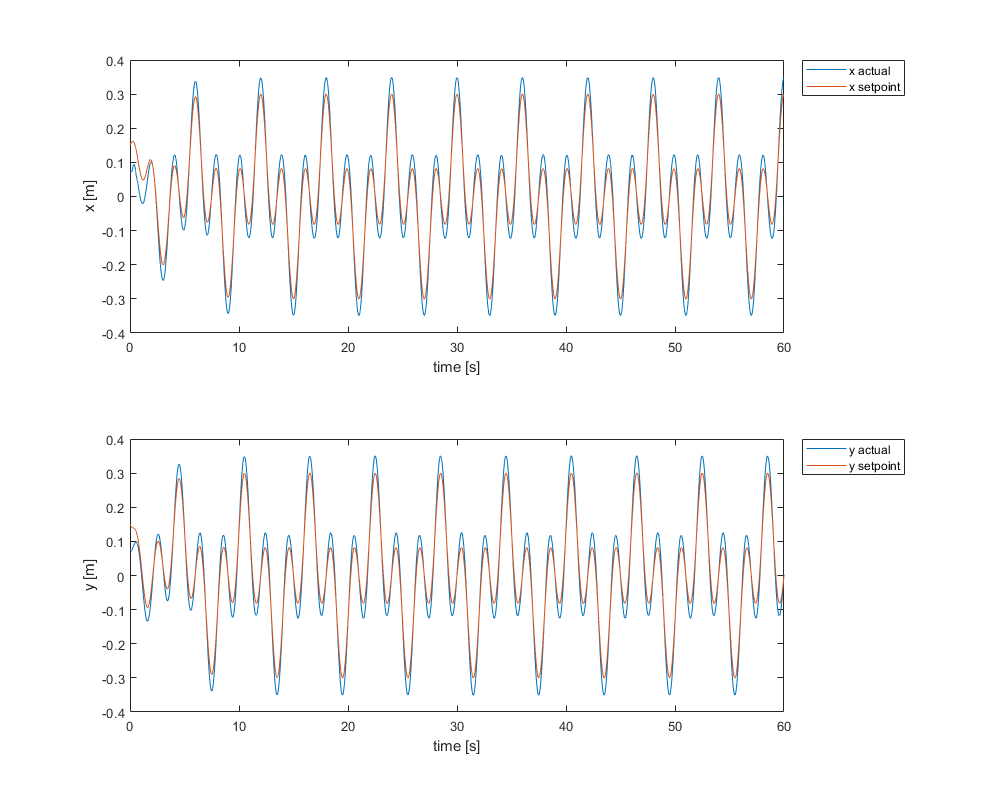

trajs = figure;
trajs.Position = [600 200 1000 800];
subplot(2,1,1)
plot(simout_Ang_In_SM.tout,simout_Ang_In_SM.x(:,1), simout_Ang_In_SM.tout,simout_Ang_In_SM.x_s_vec(:,1)) 
legend('x actual', 'x setpoint', 'Location', 'bestoutside')
xlabel('time [s]')
ylabel('x [m]')

subplot(2,1,2)
plot(simout_Ang_In_SM.tout,simout_Ang_In_SM.x(:,5), simout_Ang_In_SM.tout,simout_Ang_In_SM.y_s_vec(:,1)) 
xlabel('time [s]')
ylabel('y [m]')
legend('y actual', 'y setpoint', 'Location', 'bestoutside')

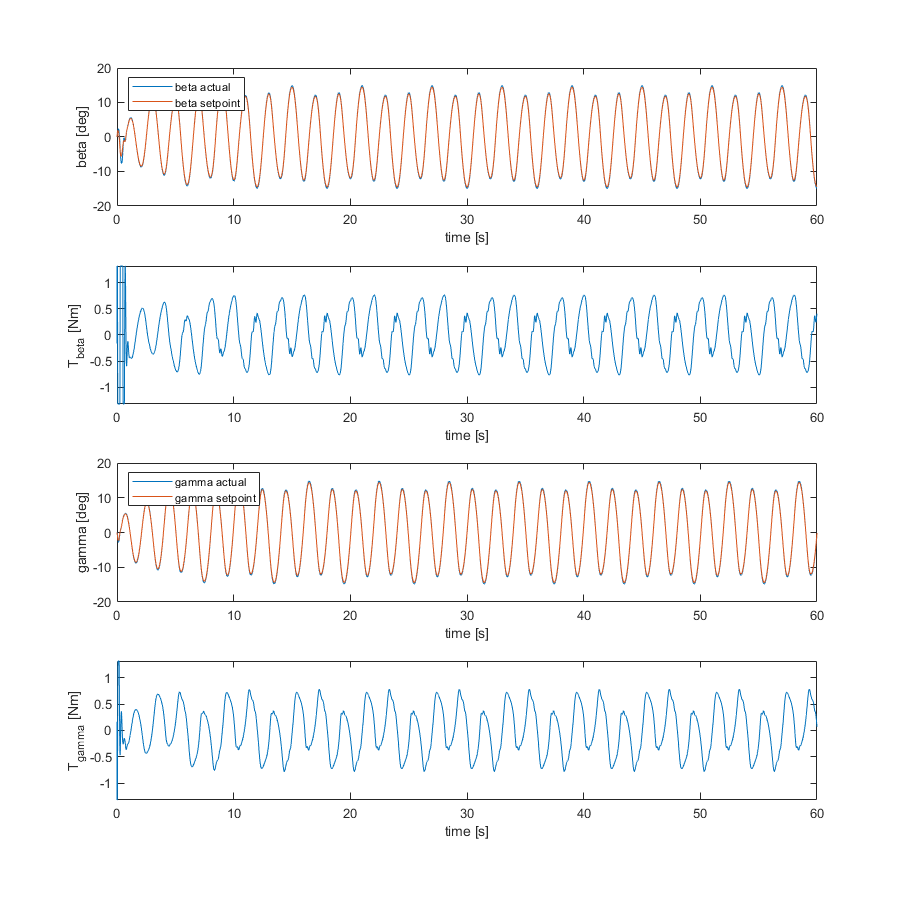


angles = figure;
angles.Position = [600 200 1200 1200];
subplot(4,1,1)
plot(simout_Ang_In_SM.tout,rad2deg(simout_Ang_In_SM.ILC_beta(:,2)), simout_Ang_In_SM.tout,rad2deg(simout_Ang_In_SM.ILC_beta(:,1))) 
legend('beta actual', 'beta setpoint', 'Location', 'northwest')
xlabel('time [s]')
ylabel('beta [deg]')

subplot(4,1,2)
plot(simout_Ang_In_SM.tout, simout_Ang_In_SM.u(:,1))
xlabel('time [s]')
ylabel('T_{beta} [Nm]')

subplot(4,1,3)
plot(simout_Ang_In_SM.tout,rad2deg(simout_Ang_In_SM.ILC_gamma(:,2)), simout_Ang_In_SM.tout,rad2deg(simout_Ang_In_SM.ILC_gamma(:,1))) 
legend('gamma actual', 'gamma setpoint', 'Location', 'northwest')
xlabel('time [s]')
ylabel('gamma [deg]')
legend('gamma actual', 'gamma setpoint')

subplot(4,1,4)
plot(simout_Ang_In_SM.tout, simout_Ang_In_SM.u(:,2))
xlabel('time [s]')
ylabel('T_{gamma} [Nm]')

### Animate Responses

n = 1;
%t_window = 2*pi/omega_sim*d*n; %Print n cycles worth of trajectory history
t_window = 2*omega_sim

t_window = 2.0944

frac = 1;
i_plot = round(length(simout_Ang_In_SM.tout)/frac)

i_plot = 14954

Animate_Response(simout_Ang_In_SM.x(1,1:i_plot),simout_Ang_In_SM.x_s_vec(1:i_plot,1),...
    simout_Ang_In_SM.x(5,1:i_plot),simout_Ang_In_SM.y_s_vec(1:i_plot,1),simout_Ang_In_SM.tout(1:i_plot),25,'Ang_in_SM.gif', r_sim, t_window)

Index in position 2 exceeds array bounds. Index must not exceed 8.

% %view_vec = 2;
% % Animate_Response_3D(simout_Ang_In_SM.x,simout_Ang_In_SM.tout,25,'try_3D_tpdwnView.gif',VDefs, view_vec)
view_vec = [140 40];
Animate_Response_3D(simout_Ang_In_SM.x,simout_Ang_In_SM.tout,25,'Ang_in_SM_3D.gif',VDefs, view_vec)